## Naïve Bayes Analysis Part 1

In this script Matlab's automated hyperparameter optimization search is used to:

- Find out if dataset normalisation performs better.

- Find which distribution name is better (normal or kernel?).

- Find the optimal range of kernel smoothing widths.

- Investigate the prior distributions created by default, and those calculated from the training dataset.

- Compare the performance of the dataset with all features vs the dataset with features removed

### Initial Analysis from a Naïve Bayes perspective dataset NOT normalised


clear
clc
clf
close all
% loads the letter dataset 
load letterDatasetClass.mat

letterDataset = letterDatasetNotNormalised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);
% start timer
startTime = cputime

startTime = 923.3906

% get a default class
nBayes = NBayesClass.getDefaultInstance(letterDataset);
nBayes.nBayesModel.Prior

ans =     0.0391    0.0381    0.0381    0.0399    0.0384    0.0378    0.0393    0.0361    0.0379    0.0361    0.0367    0.0384    0.0396    0.0383    0.0382    0.0407    0.0386    0.0375    0.0381    0.0413    0.0404    0.0393    0.0377    0.0387    0.0394    0.0366


[dfltLTrainLoss, dfltTestLoss] = nBayes.getModelLoss();
nBayes.setPriorDistributionEmpirical();

prior =     0.0413
    0.0379
    0.0399
    0.0383
    0.0393
    0.0391
    0.0396
    0.0387
    0.0382
    0.0375


nBayes.nBayesModel.Prior

ans =     0.0413    0.0379    0.0399    0.0383    0.0393    0.0391    0.0396    0.0387    0.0382    0.0375    0.0381    0.0361    0.0381    0.0361    0.0384    0.0381    0.0384    0.0394    0.0386    0.0407    0.0393    0.0377    0.0404    0.0378    0.0366    0.0368


[empTrainLoss, emptTestLoss] = nBayes.getModelLoss();
fprintf("Default Training Loss:   %0.04f Test Loss %0.04f\n", dfltLTrainLoss, dfltTestLoss);

Default Training Loss:   0.3539 Test Loss 0.3668


fprintf("Empirical Training Loss: %0.04f Test Loss %0.04f\n", empTrainLoss, emptTestLoss);

Empirical Training Loss: 0.3549 Test Loss 0.3678


Set prior distribution to an empirical distribution

model = nBayes.setPriorDistributionEmpirical();

prior =     0.0413
    0.0379
    0.0399
    0.0383
    0.0393
    0.0391
    0.0396
    0.0387
    0.0382
    0.0375


cvModel = crossval(model);
modelLoss = kfoldLoss(cvModel);
crossValModel = crossval(model);
fprintf("KFold Loss:: %0.04f\n", kfoldLoss(crossValModel));

KFold Loss:: 0.3595


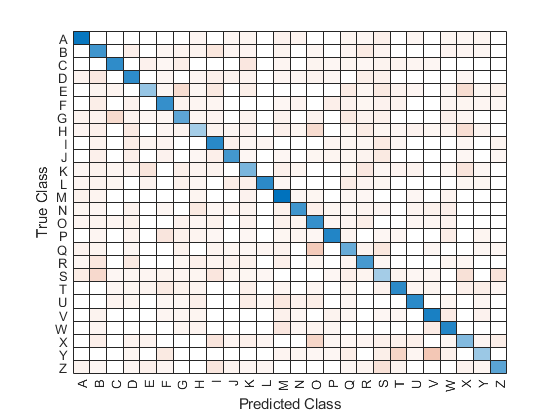

[predicted, score] = resubPredict(model);
confusionMat = confusionchart(categorical(Y), predicted);

Look at the classifiers that have been setup for each attribute. There are 16 of them, each one configurable.

disp(model.DistributionNames(:,:));

  Columns 1 through 7

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}

  Columns 8 through 14

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}

  Columns 15 through 16

    {'normal'}    {'normal'}



[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.3549 Test loss: 0.3678, normalised dataset: 0


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 6.4375

disp(nBayes);

  NBayesClass with properties:

          randomSeed: 300
               debug: 1
             dataset: [1×1 LetterDatasetClass]
         nBayesModel: [1×1 ClassificationNaiveBayes]
                   x: [16000×16 table]
                   y: [16000×1 table]
                  xt: [4000×16 table]
                  yt: [4000×1 table]
    distNamesDefault: {1×16 cell}
     distNamesKernel: {1×16 cell}



#### Try Optimization

% start timer
startTime = cputime

startTime = 930.2188

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33644 |      70.425 |     0.33644 |     0.33644 |       kernel |        1.287 |


|    2 | Accept |     0.35725 |     0.46443 |     0.33644 |     0.34644 |       normal |            - |


|    3 | Accept |     0.35725 |     0.44708 |     0.33644 |     0.33644 |       normal |            - |


|    4 | Accept |     0.51019 |      69.693 |     0.33644 |     0.33644 |       kernel |       8.6162 |


|    5 | Best   |     0.25006 |       42.94 |     0.25006 |     0.25007 |       kernel |      0.30805 |


|    6 | Best   |     0.24919 |      43.181 |     0.24919 |     0.24914 |       kernel |      0.25009 |


|    7 | Accept |     0.24919 |      43.009 |     0.24919 |     0.24916 |       kernel |      0.25013 |


|    8 | Accept |     0.24919 |      43.237 |     0.24919 |     0.24917 |       kernel |      0.25022 |


|    9 | Accept |     0.24919 |      43.132 |     0.24919 |     0.24917 |       kernel |      0.26337 |


|   10 | Accept |     0.24919 |      43.234 |     0.24919 |     0.24917 |       kernel |      0.25043 |


|   11 | Accept |     0.27044 |       55.81 |     0.24919 |     0.24922 |       kernel |      0.61428 |


|   12 | Accept |     0.61375 |      70.164 |     0.24919 |      0.2492 |       kernel |       14.998 |


|   13 | Accept |     0.24938 |       42.85 |     0.24919 |     0.24924 |       kernel |      0.27578 |


|   14 | Accept |     0.44525 |      75.647 |     0.24919 |     0.24919 |       kernel |       3.1633 |


|   15 | Accept |     0.24931 |      43.153 |     0.24919 |      0.2492 |       kernel |      0.26992 |


|   16 | Accept |     0.25769 |      43.193 |     0.24919 |     0.24921 |       kernel |      0.44953 |


|   17 | Accept |     0.29875 |      63.036 |     0.24919 |     0.24921 |       kernel |      0.87686 |


|   18 | Accept |     0.48094 |      74.947 |     0.24919 |     0.24921 |       kernel |       5.1232 |


|   19 | Accept |      0.2525 |      43.468 |     0.24919 |     0.24921 |       kernel |      0.37089 |


|   20 | Accept |     0.39281 |      73.156 |     0.24919 |     0.24921 |       kernel |       1.9431 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25031 |      42.039 |     0.24919 |     0.24919 |       kernel |      0.33501 |


|   22 | Accept |     0.26306 |      54.322 |     0.24919 |     0.24919 |       kernel |      0.52137 |


|   23 | Best   |     0.24913 |      42.239 |     0.24913 |     0.24918 |       kernel |      0.25916 |


|   24 | Accept |     0.24944 |      42.269 |     0.24913 |     0.24918 |       kernel |      0.28773 |


|   25 | Accept |     0.24913 |      42.452 |     0.24913 |     0.24918 |       kernel |      0.25891 |


|   26 | Accept |     0.24913 |      43.434 |     0.24913 |     0.24917 |       kernel |       0.2586 |


|   27 | Accept |     0.54869 |      69.116 |     0.24913 |     0.24917 |       kernel |       11.674 |


|   28 | Accept |     0.28331 |      53.504 |     0.24913 |     0.24917 |       kernel |      0.72876 |


|   29 | Accept |       0.423 |      72.265 |     0.24913 |     0.24917 |       kernel |       2.4778 |


|   30 | Accept |      0.4925 |      70.756 |     0.24913 |     0.24917 |       kernel |       6.5632 |


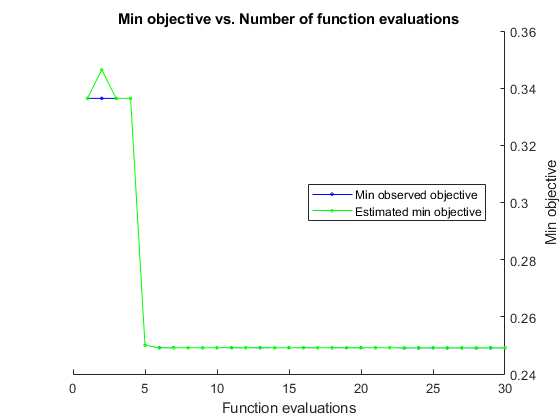

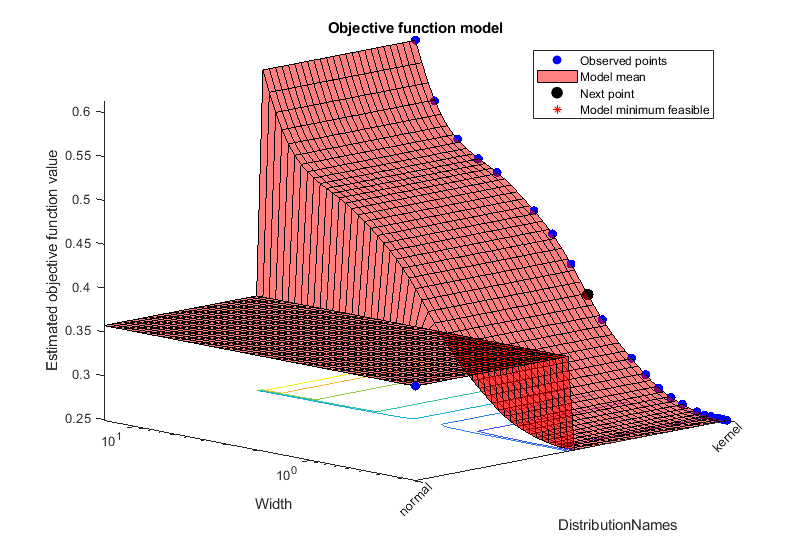


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1544.7132 seconds
Total objective function evaluation time: 1517.5841

Best observed feasible point:
    DistributionNames     Width 
    _________________    _______

         kernel          0.25916

Observed objective function value = 0.24913
Estimated objective function value = 0.24917
Function evaluation time = 42.2392

Best estimated feasible point (according to models):
    DistributionNames     Width 
    _________________    _______

         kernel          0.25916

Estimated objective function value = 0.24917
Estimated function evaluation time = 42.7089



letterDataset = letterDatasetNotNormalised;
nBayes = NBayesClass.getDefaultInstance(letterDataset);
nBayes.fitMatlabHyperparameterOptimization();


[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.2339 Test loss: 0.2510, normalised dataset: 0



endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 7318.4688

disp(nBayes);

  NBayesClass with properties:

          randomSeed: 300
               debug: 1
             dataset: [1×1 LetterDatasetClass]
         nBayesModel: [1×1 ClassificationNaiveBayes]
                   x: [16000×16 table]
                   y: [16000×1 table]
                  xt: [4000×16 table]
                  yt: [4000×1 table]
    distNamesDefault: {1×16 cell}
     distNamesKernel: {1×16 cell}



### Try 'kernel' distribution on NOT Normalised dataset

startTime = cputime

startTime = 8.2496e+03

letterDataset = letterDatasetNotNormalised;
Bayes = NBayesClass.getKernelInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();

prior =     0.0413
    0.0379
    0.0399
    0.0383
    0.0393
    0.0391
    0.0396
    0.0387
    0.0382
    0.0375


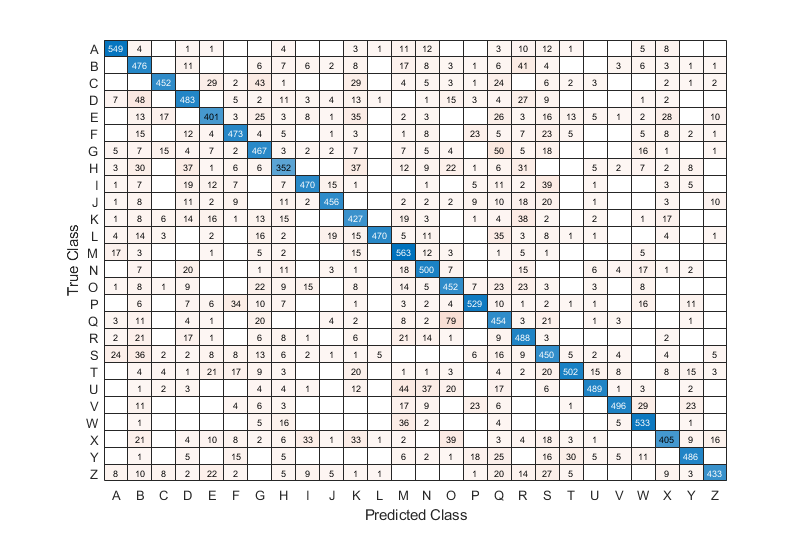

predictions = resubPredict(model);
confusionMat = confusionchart(categorical(Y), predictions);

[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.2342 Test loss: 0.2508, normalised dataset: 0


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 420.9531

disp(nBayes);

  NBayesClass with properties:

          randomSeed: 300
               debug: 1
             dataset: [1×1 LetterDatasetClass]
         nBayesModel: [1×1 ClassificationNaiveBayes]
                   x: [16000×16 table]
                   y: [16000×1 table]
                  xt: [4000×16 table]
                  yt: [4000×1 table]
    distNamesDefault: {1×16 cell}
     distNamesKernel: {1×16 cell}



#### Try Optimization

% start timer
startTime = cputime

startTime = 8.6711e+03

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33644 |       69.16 |     0.33644 |     0.33644 |       kernel |        1.287 |


|    2 | Accept |     0.35725 |     0.41568 |     0.33644 |     0.34644 |       normal |            - |


|    3 | Accept |     0.35725 |     0.42604 |     0.33644 |     0.33644 |       normal |            - |


|    4 | Accept |     0.51019 |      74.165 |     0.33644 |     0.33644 |       kernel |       8.6162 |


|    5 | Best   |     0.25006 |      42.403 |     0.25006 |     0.25007 |       kernel |      0.30805 |


|    6 | Best   |     0.24919 |      42.634 |     0.24919 |     0.24914 |       kernel |      0.25009 |


|    7 | Accept |     0.24919 |      42.441 |     0.24919 |     0.24916 |       kernel |      0.25013 |


|    8 | Accept |     0.24919 |      42.733 |     0.24919 |     0.24917 |       kernel |      0.25022 |


|    9 | Accept |     0.24919 |      42.767 |     0.24919 |     0.24917 |       kernel |      0.26337 |


|   10 | Accept |     0.24919 |      42.907 |     0.24919 |     0.24917 |       kernel |      0.25043 |


|   11 | Accept |     0.27044 |      54.883 |     0.24919 |     0.24922 |       kernel |      0.61428 |


|   12 | Accept |     0.61375 |      69.306 |     0.24919 |      0.2492 |       kernel |       14.998 |


|   13 | Accept |     0.24938 |       42.48 |     0.24919 |     0.24924 |       kernel |      0.27578 |


|   14 | Accept |     0.44525 |      72.018 |     0.24919 |     0.24919 |       kernel |       3.1633 |


|   15 | Accept |     0.24931 |      42.205 |     0.24919 |      0.2492 |       kernel |      0.26992 |


|   16 | Accept |     0.25769 |      42.286 |     0.24919 |     0.24921 |       kernel |      0.44953 |


|   17 | Accept |     0.29875 |      62.255 |     0.24919 |     0.24921 |       kernel |      0.87686 |


|   18 | Accept |     0.48094 |      74.511 |     0.24919 |     0.24921 |       kernel |       5.1232 |


|   19 | Accept |      0.2525 |      42.916 |     0.24919 |     0.24921 |       kernel |      0.37089 |


|   20 | Accept |     0.39281 |      73.417 |     0.24919 |     0.24921 |       kernel |       1.9431 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25031 |      42.113 |     0.24919 |     0.24919 |       kernel |      0.33501 |


|   22 | Accept |     0.26306 |      54.395 |     0.24919 |     0.24919 |       kernel |      0.52137 |


|   23 | Best   |     0.24913 |      42.459 |     0.24913 |     0.24918 |       kernel |      0.25916 |


|   24 | Accept |     0.24944 |      42.379 |     0.24913 |     0.24918 |       kernel |      0.28773 |


|   25 | Accept |     0.24913 |      42.732 |     0.24913 |     0.24918 |       kernel |      0.25891 |


|   26 | Accept |     0.24913 |      42.835 |     0.24913 |     0.24917 |       kernel |       0.2586 |


|   27 | Accept |     0.54869 |      69.888 |     0.24913 |     0.24917 |       kernel |       11.674 |


|   28 | Accept |     0.28331 |      54.175 |     0.24913 |     0.24917 |       kernel |      0.72876 |


|   29 | Accept |       0.423 |      74.434 |     0.24913 |     0.24917 |       kernel |       2.4778 |


|   30 | Accept |      0.4925 |      74.718 |     0.24913 |     0.24917 |       kernel |       6.5632 |



__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1542.482 seconds
Total objective function evaluation time: 1516.4573

Best observed feasible point:
    DistributionNames     Width 
    _________________    _______

         kernel          0.25916

Observed objective function value = 0.24913
Estimated objective function value = 0.24917
Function evaluation time = 42.459

Best estimated feasible point (according to models):
    DistributionNames     Width 
    _________________    _______

         kernel          0.25916

Estimated objective function value = 0.24917
Estimated function evaluation time = 42.3896



letterDataset = letterDatasetNotNormalised;
nBayes = NBayesClass(letterDataset);
nBayes.fitMatlabHyperparameterOptimization();

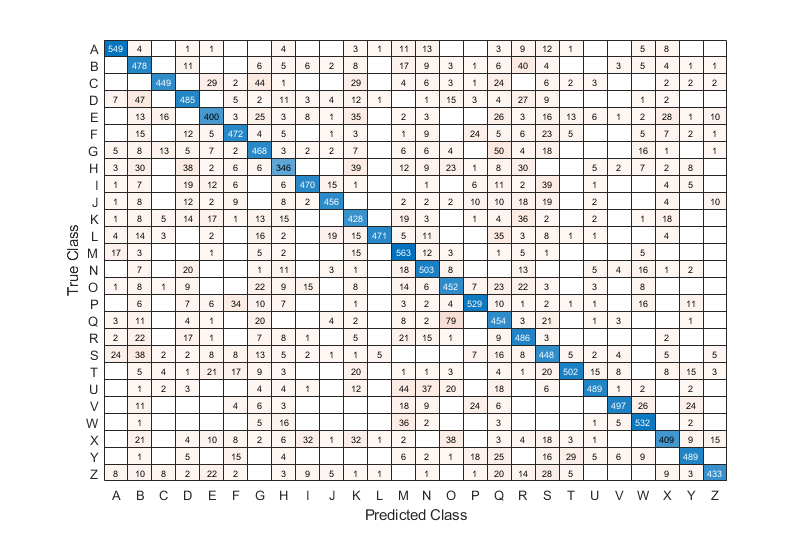

predictions = resubPredict(nBayes.nBayesModel);
confusionMat = confusionchart(categorical(Y), predictions);

[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.2339 Test loss: 0.2510, normalised dataset: 0


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 7530.1094

disp(nBayes);

  NBayesClass with properties:

          randomSeed: 300
               debug: 1
             dataset: [1×1 LetterDatasetClass]
         nBayesModel: [1×1 ClassificationNaiveBayes]
                   x: [16000×16 table]
                   y: [16000×1 table]
                  xt: [4000×16 table]
                  yt: [4000×1 table]
    distNamesDefault: {1×16 cell}
     distNamesKernel: {1×16 cell}



### Try Normalised Dataset

clear
clc
clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetStandardised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);

startTime = cputime;
% get a kernel class
nBayes = NBayesClass.getDefaultInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();

prior =     0.0413
    0.0379
    0.0399
    0.0383
    0.0393
    0.0391
    0.0396
    0.0387
    0.0382
    0.0375


predictions = resubPredict(model);
confusionMat = confusionchart(categorical(Y), predictions);

[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.3549 Test loss: 0.3678, normalised dataset: 1


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 2.4375

disp(nBayes);

  NBayesClass with properties:

          randomSeed: 300
               debug: 1
             dataset: [1×1 LetterDatasetClass]
         nBayesModel: [1×1 ClassificationNaiveBayes]
                   x: [16000×16 table]
                   y: [16000×1 table]
                  xt: [4000×16 table]
                  yt: [4000×1 table]
    distNamesDefault: {1×16 cell}
     distNamesKernel: {1×16 cell}



#### Try Optimization (MATLab sets distribution to Kernel, normal (gaussian)

% start timer
startTime = cputime

startTime = 1.6205e+04

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33375 |      69.228 |     0.33375 |     0.33375 |       kernel |       0.5295 |


|    2 | Accept |     0.35725 |     0.44156 |     0.33375 |     0.34505 |       normal |            - |


|    3 | Accept |     0.35725 |     0.42709 |     0.33375 |     0.33375 |       normal |            - |


|    4 | Accept |       0.544 |      68.516 |     0.33375 |     0.33376 |       kernel |       5.0418 |


|    5 | Best   |      0.2495 |      26.413 |      0.2495 |     0.24951 |       kernel |     0.097246 |


|    6 | Accept |     0.25506 |      42.023 |      0.2495 |     0.24948 |       kernel |      0.16486 |


|    7 | Accept |      0.2495 |        24.3 |      0.2495 |     0.24922 |       kernel |     0.075972 |


|    8 | Accept |     0.24963 |      28.661 |      0.2495 |     0.24941 |       kernel |     0.097976 |


|    9 | Accept |      0.2495 |      25.969 |      0.2495 |     0.24941 |       kernel |     0.075985 |


|   10 | Accept |      0.2495 |      26.183 |      0.2495 |     0.24941 |       kernel |     0.092949 |


|   11 | Accept |     0.24956 |      25.971 |      0.2495 |     0.24943 |       kernel |     0.090648 |


|   12 | Accept |      0.2495 |       25.87 |      0.2495 |     0.24943 |       kernel |     0.075988 |


|   13 | Accept |     0.74075 |      76.002 |      0.2495 |      0.2495 |       kernel |       9.7236 |


|   14 | Accept |     0.25006 |      37.831 |      0.2495 |     0.24949 |       kernel |      0.12165 |


|   15 | Accept |      0.2495 |       26.13 |      0.2495 |     0.24949 |       kernel |     0.085342 |


|   16 | Accept |     0.24994 |      34.455 |      0.2495 |     0.24952 |       kernel |      0.10978 |


|   17 | Accept |      0.2495 |      25.893 |      0.2495 |     0.24952 |       kernel |     0.076067 |


|   18 | Accept |     0.46381 |      79.004 |      0.2495 |     0.24952 |       kernel |       1.5736 |


|   19 | Accept |      0.2495 |      26.132 |      0.2495 |      0.2495 |       kernel |     0.084293 |


|   20 | Accept |     0.28288 |      61.494 |      0.2495 |      0.2495 |       kernel |      0.31036 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.49988 |      78.926 |      0.2495 |      0.2495 |       kernel |       2.7621 |


|   22 | Accept |     0.39544 |      80.664 |      0.2495 |     0.24947 |       kernel |      0.87436 |


|   23 | Accept |     0.26456 |      52.078 |      0.2495 |     0.24947 |       kernel |      0.22589 |


|   24 | Accept |      0.2515 |      42.345 |      0.2495 |     0.24948 |       kernel |      0.14167 |


|   25 | Accept |     0.30419 |      69.871 |      0.2495 |     0.24948 |       kernel |      0.39711 |


|   26 | Accept |     0.25988 |      46.999 |      0.2495 |     0.24949 |       kernel |      0.19193 |


|   27 | Accept |      0.2495 |      25.607 |      0.2495 |     0.24949 |       kernel |     0.079753 |


|   28 | Accept |     0.25056 |      40.937 |      0.2495 |      0.2495 |       kernel |      0.13008 |


|   29 | Accept |     0.24988 |      30.395 |      0.2495 |     0.24949 |       kernel |      0.10335 |


|   30 | Accept |      0.2495 |      25.802 |      0.2495 |     0.24949 |       kernel |     0.079577 |


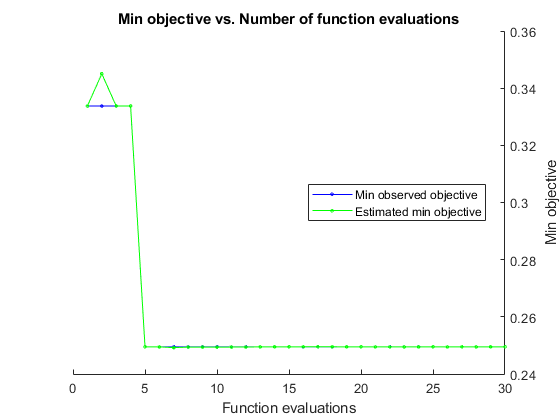

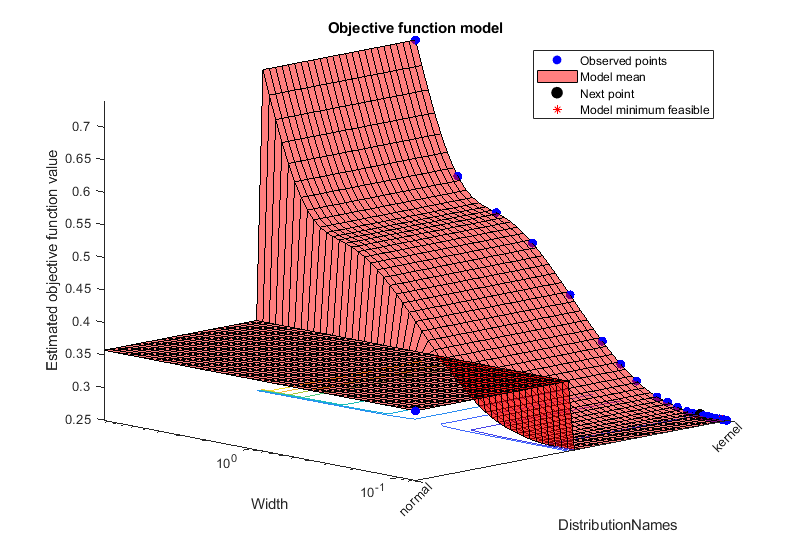


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1248.6127 seconds
Total objective function evaluation time: 1224.566

Best observed feasible point:
    DistributionNames     Width  
    _________________    ________

         kernel          0.097246

Observed objective function value = 0.2495
Estimated objective function value = 0.24959
Function evaluation time = 26.4127

Best estimated feasible point (according to models):
    DistributionNames     Width  
    _________________    ________

         kernel          0.079577

Estimated objective function value = 0.24949
Estimated function evaluation time = 25.4626



letterDataset = letterDatasetStandardised;
nBayes = NBayesClass(letterDataset);
nBayes.fitMatlabHyperparameterOptimization();

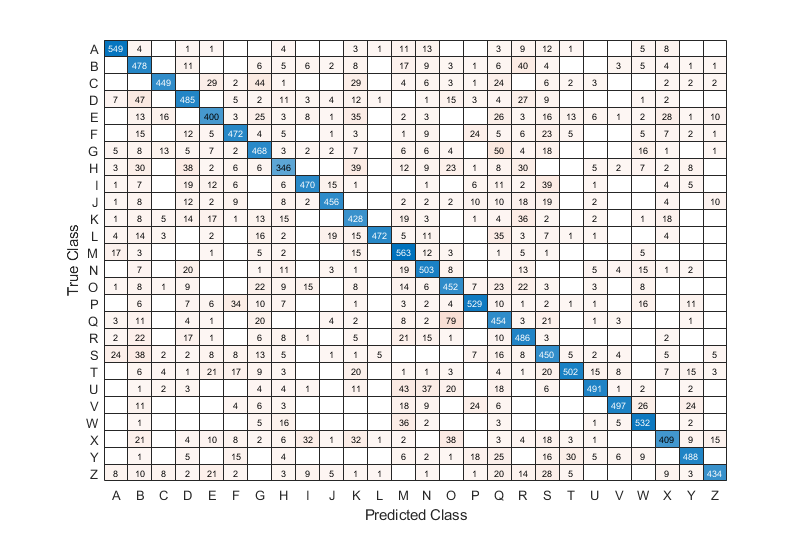

predictions = resubPredict(nBayes.nBayesModel);
confusionMat = confusionchart(categorical(Y), predictions);

[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.2336 Test loss: 0.2525, normalised dataset: 1


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 4999.4844

disp(nBayes);

  NBayesClass with properties:

          randomSeed: 300
               debug: 1
             dataset: [1×1 LetterDatasetClass]
         nBayesModel: [1×1 ClassificationNaiveBayes]
                   x: [16000×16 table]
                   y: [16000×1 table]
                  xt: [4000×16 table]
                  yt: [4000×1 table]
    distNamesDefault: {1×16 cell}
     distNamesKernel: {1×16 cell}



### Try 'kernel' distribution on Normalised dataset

clear
clc
clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetStandardised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);

startTime = cputime;
% get a kernel class
nBayes = NBayesClass.getKernelInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();

prior =     0.0413
    0.0379
    0.0399
    0.0383
    0.0393
    0.0391
    0.0396
    0.0387
    0.0382
    0.0375


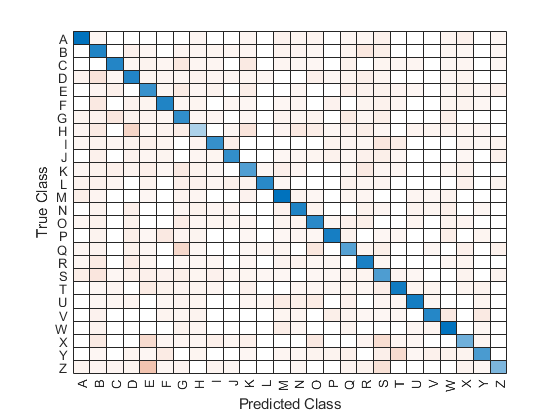

predictions = resubPredict(model);
confusionMat = confusionchart(categorical(Y), predictions);


[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.04f Test loss: %0.04f, normalised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.3040 Test loss: 0.3213, normalised dataset: 1


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 596.1563

disp(nBayes);

  NBayesClass with properties:

          randomSeed: 300
               debug: 1
             dataset: [1×1 LetterDatasetClass]
         nBayesModel: [1×1 ClassificationNaiveBayes]
                   x: [16000×16 table]
                   y: [16000×1 table]
                  xt: [4000×16 table]
                  yt: [4000×1 table]
    distNamesDefault: {1×16 cell}
     distNamesKernel: {1×16 cell}



### Results

- Normalisation of the attributes has no effect.

- The kernal distribution is better than the normal distribution.

- The kernel width of 0.017277 is the best one when all attributes are used.

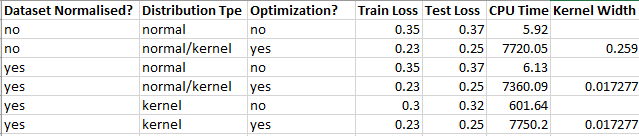

Based in these results, a final normalised, kernel run is performed on the **dataset with the highly correlated features removed.**

### Try Reduced Attribute Standardised Dataset Test Run

clear
clc
clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetStandardised;
letterDataset.removeColumn("xBox");
letterDataset.removeColumn("yBox");
letterDataset.removeColumn("width");
letterDataset.removeColumn("height");
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);

startTime = cputime;
% get a kernel class
nBayes = NBayesClass.getKernelInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();

prior =     0.0413
    0.0379
    0.0399
    0.0383
    0.0393
    0.0391
    0.0396
    0.0387
    0.0382
    0.0375


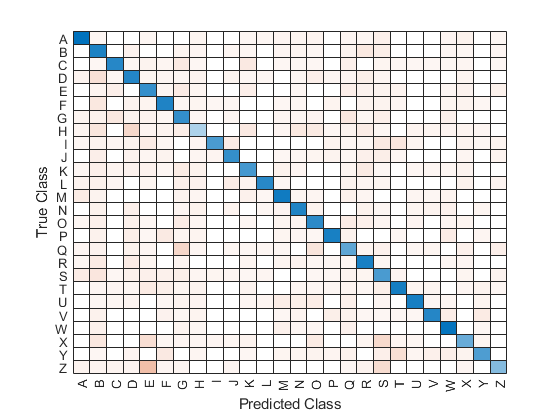

predictions = resubPredict(model);
confusionMat = confusionchart(categorical(Y), predictions);


[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.04f Test loss: %0.04f, standardised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.3059 Test loss: 0.3123, standardised dataset: 1


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 431.8594

disp(nBayes);

  NBayesClass with properties:

          randomSeed: 300
               debug: 1
             dataset: [1×1 LetterDatasetClass]
         nBayesModel: [1×1 ClassificationNaiveBayes]
                   x: [16000×12 table]
                   y: [16000×1 table]
                  xt: [4000×12 table]
                  yt: [4000×1 table]
    distNamesDefault: {1×12 cell}
     distNamesKernel: {1×12 cell}



#### Try Optimization (uses letterDataset defined in previous cell)

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33531 |      51.786 |     0.33531 |     0.33531 |       kernel |      0.59875 |


|    2 | Accept |       0.347 |     0.38354 |     0.33531 |     0.34093 |       normal |            - |


|    3 | Accept |       0.347 |     0.40078 |     0.33531 |     0.33531 |       normal |            - |


|    4 | Accept |     0.54338 |      51.129 |     0.33531 |     0.33532 |       kernel |       5.1836 |


|    5 | Best   |     0.24844 |       18.99 |     0.24844 |     0.24845 |       kernel |       0.0932 |


|    6 | Accept |     0.24844 |      20.124 |     0.24844 |     0.24842 |       kernel |     0.096024 |


|    7 | Accept |     0.25038 |      30.117 |     0.24844 |     0.24831 |       kernel |      0.15132 |


|    8 | Accept |     0.24863 |      27.783 |     0.24844 |     0.24845 |       kernel |       0.1144 |


|    9 | Accept |     0.24856 |      26.065 |     0.24844 |     0.24836 |       kernel |      0.11119 |


|   10 | Accept |     0.24863 |      26.115 |     0.24844 |     0.24842 |       kernel |      0.10965 |


|   11 | Accept |     0.24844 |      19.522 |     0.24844 |     0.24842 |       kernel |     0.093284 |


|   12 | Accept |     0.75038 |       50.85 |     0.24844 |     0.24845 |       kernel |       9.7261 |


|   13 | Accept |     0.26088 |      38.563 |     0.24844 |     0.24842 |       kernel |       0.2395 |


|   14 | Accept |     0.24844 |      19.364 |     0.24844 |     0.24842 |       kernel |     0.093226 |


|   15 | Accept |     0.24844 |      19.257 |     0.24844 |     0.24842 |       kernel |     0.093274 |


|   16 | Accept |     0.45938 |      52.154 |     0.24844 |     0.24841 |       kernel |       1.7272 |


|   17 | Accept |      0.2485 |      22.584 |     0.24844 |     0.24842 |       kernel |      0.10246 |


|   18 | Accept |     0.29025 |      46.035 |     0.24844 |     0.24842 |       kernel |      0.38198 |


|   19 | Accept |     0.49269 |       58.21 |     0.24844 |     0.24843 |       kernel |       2.9322 |


|   20 | Accept |      0.3965 |      57.423 |     0.24844 |     0.24843 |       kernel |      0.98065 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25525 |      34.738 |     0.24844 |     0.24844 |       kernel |      0.19066 |


|   22 | Accept |     0.27113 |      41.381 |     0.24844 |     0.24844 |       kernel |      0.29783 |


|   23 | Accept |     0.24925 |      29.627 |     0.24844 |     0.24844 |       kernel |      0.13231 |


|   24 | Accept |     0.25194 |      32.053 |     0.24844 |     0.24844 |       kernel |      0.16807 |


|   25 | Accept |     0.24844 |      28.361 |     0.24844 |     0.24844 |       kernel |      0.12221 |


|   26 | Accept |     0.24844 |      21.669 |     0.24844 |     0.24843 |       kernel |     0.098351 |


|   27 | Accept |     0.24863 |      27.015 |     0.24844 |     0.24843 |       kernel |      0.12018 |


|   28 | Accept |      0.3125 |      49.435 |     0.24844 |     0.24844 |       kernel |      0.47467 |


|   29 | Accept |      0.2485 |       22.21 |     0.24844 |     0.24844 |       kernel |      0.10455 |


|   30 | Accept |        0.25 |       29.44 |     0.24844 |     0.24843 |       kernel |       0.1404 |


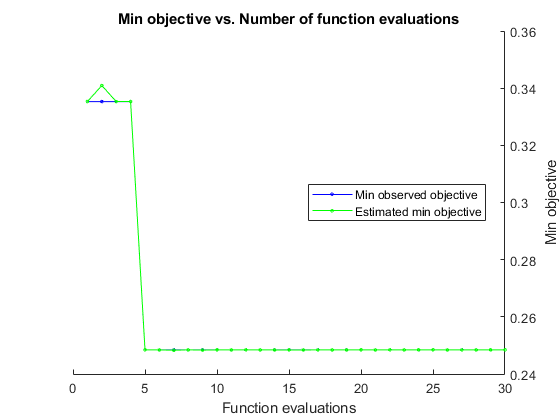

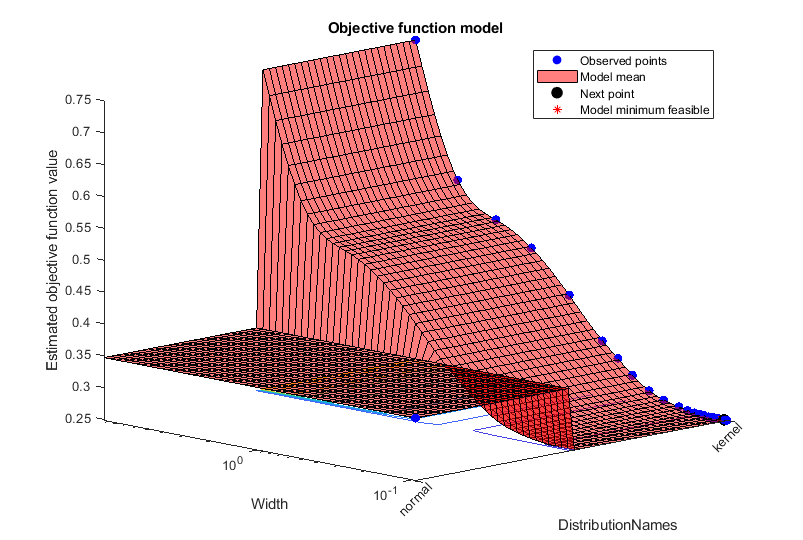


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 975.6874 seconds
Total objective function evaluation time: 952.7865

Best observed feasible point:
    DistributionNames    Width 
    _________________    ______

         kernel          0.0932

Observed objective function value = 0.24844
Estimated objective function value = 0.24847
Function evaluation time = 18.9902

Best estimated feasible point (according to models):
    DistributionNames     Width  
    _________________    ________

         kernel          0.098351

Estimated objective function value = 0.24843
Estimated function evaluation time = 21.2934



nBayes = NBayesClass.getKernelInstance(letterDataset);
nBayes.fitMatlabHyperparameterOptimization();

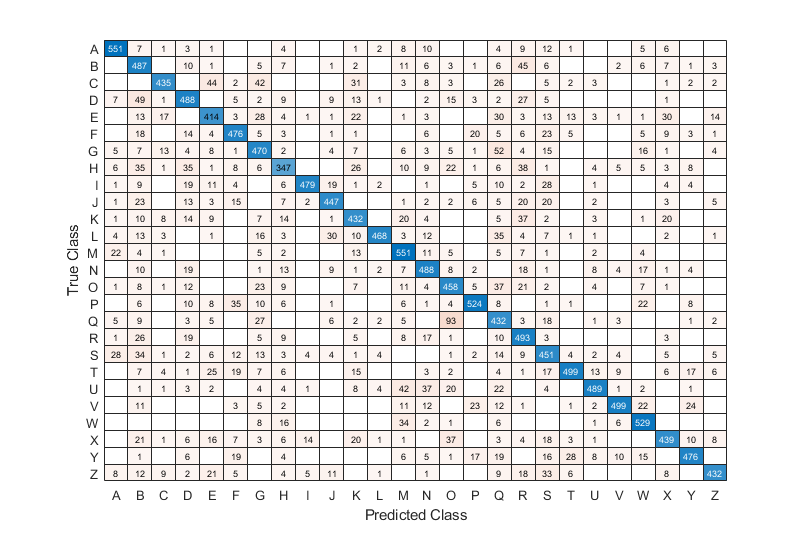


predictions = resubPredict(nBayes.nBayesModel);
confusionMat = confusionchart(categorical(Y), predictions);


[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.04f Test loss: %0.04f, standardised dataset: %d\n", ...
    trainingLoss, testLoss, nBayes.dataset.isStandardised);

Training loss: 0.2341 Test loss: 0.2518, standardised dataset: 1


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 4642.9375

disp(nBayes);

  NBayesClass with properties:

          randomSeed: 300
               debug: 1
             dataset: [1×1 LetterDatasetClass]
         nBayesModel: [1×1 ClassificationNaiveBayes]
                   x: [16000×12 table]
                   y: [16000×1 table]
                  xt: [4000×12 table]
                  yt: [4000×1 table]
    distNamesDefault: {1×12 cell}
     distNamesKernel: {1×12 cell}



### Results Conclusion

The results from all the tests are below:

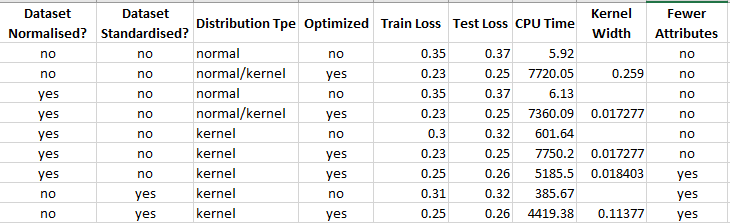

Conclusions drawn from the full dataset:

- Normalisation of the attributes has no effect.

- The kernal distribution is better than the normal distribution.

Conclusions drawn from using fewer features:

- Reducing the features has a very small effect on the training and test loss.

- Setting the prior distribution to the actual dataset distribution has little effect compared to the default. Setting it is prefereable: the values are calculated using the training dataset, it is fixed.

- The optimization task is quickest using fewer features, on a standardised dataset.

- The standardised dataset hyperparameter value for the optimized kernel width is reported as 0.11377

Further work on the dataset should use the standardised dataset with fewer features: the time reduction is great enough to justify the very small increase in loss of between 1% and 2%.

Matlab displays a warning advising the standardization of numeric predictors when optimizing using the width hyperparameter. Using the normalised dataset provides a noticeable reduction in the time taken to run the analysis tasks.